# **Relatório do Laboratório de Sinais e Sistemas**

**Q1.1**

samplerateQ1 = 16e3; % Hz
t = (0:1/samplerateQ1:2); % s
f1 = 32; % Hz
f2 = 40; % Hz
x = cos(2*pi*f1*t) + cos(2*pi*f2*t);

Com  o objetivo de fazer a medição direta do período da função x(t) pelo plot da mesma faz-se:

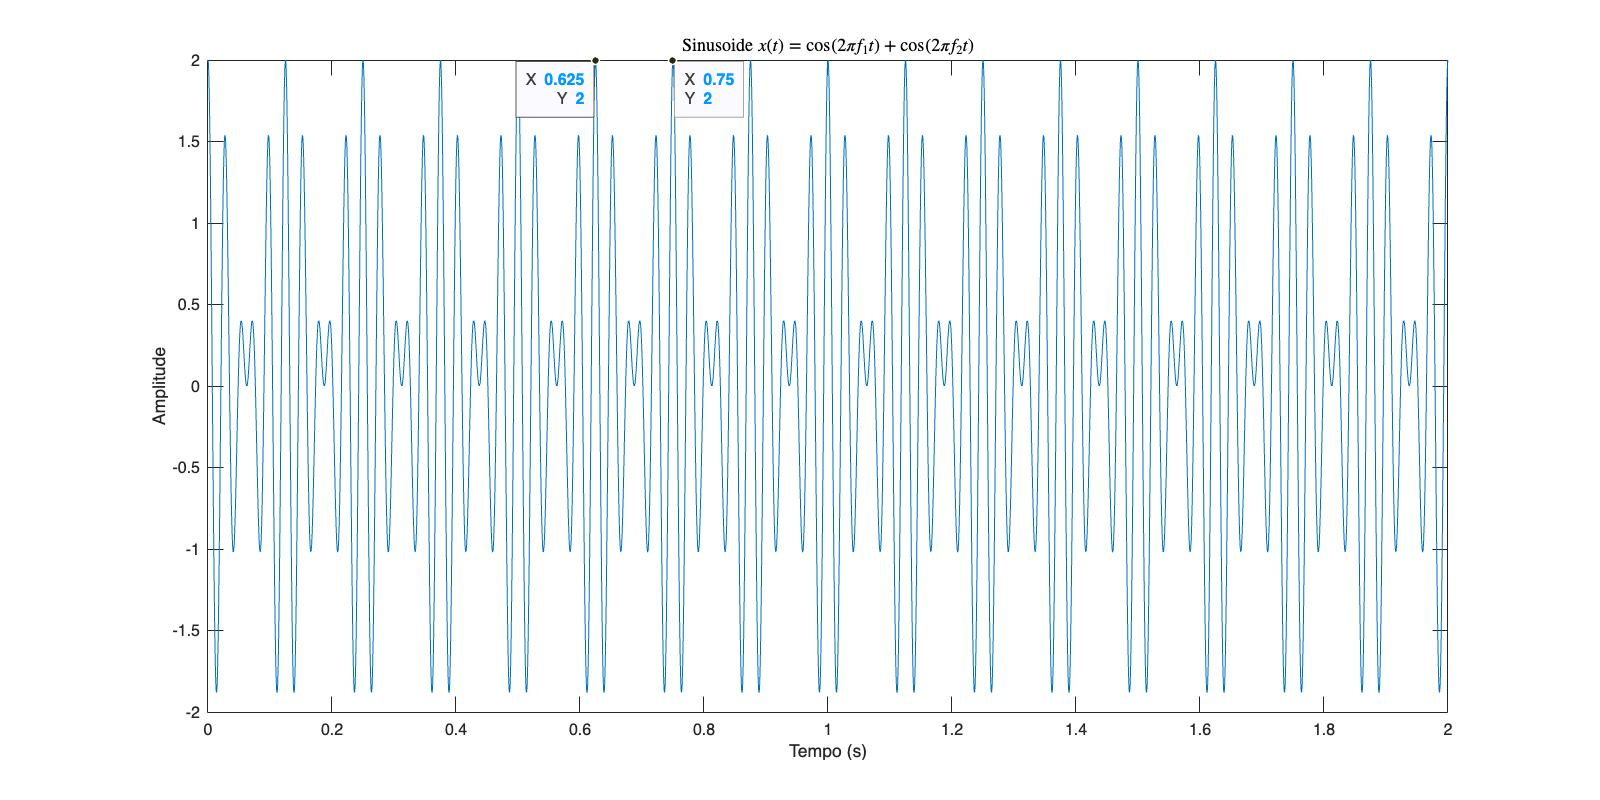

figure('Units', 'pixels', 'Position', [0, 0, 1000, 500]); 
plot(t,x);
xlabel('Tempo (s)');
ylabel('Amplitude');
title('Sinusoide $x(t) = \cos(2\pi f_1 t) + \cos(2\pi f_2 t)$', 'Interpreter', 'latex')

xlim([0.00 2.00])
ylim([-2.00 2.00])
zlim([-1.00 1.00])
 
ax = gca;
chart = ax.Children(1);
datatip(chart,0.75,2);
datatip(chart,0.625,2,"Location","southwest");

As *datatips* acima permitem-nos levam a concluir que o período medido diretamente através do plot é 0.125 (x2-x1 = 0.75-0.625 = 0.125)

Teoricamente, o período fundamental do sinal é o mínimo múltiplo comum (MMC) dos períodos fundamentais de cada cosseno.

Ao trabalhar com números racionais (como os períodos fundamentais de cada cosseno, que são o inverso das suas frequências), temos:


$$\text{MMC} = \frac{\text{MMC dos numeradores (= 1)}}{\text{MDC dos denominadores}}$$


function mmc = LCM(a,b)
    [num_a, den_a] = rat(a);
    [num_b, den_b] = rat(b);
    mmc = (lcm(num_a, num_b))/(gcd(den_a, den_b));
end
theoretical_period = LCM(1/f1, 1/f2)

theoretical_period = 0.1250

Conclui-se assim que o período medido diretamente no plot coincide com o período teórico calculado.

**Q1.2**

O período em amostras teórico corresponde a 

period_in_samples = LCM(theoretical_period, 1/samplerateQ1) * samplerateQ1

period_in_samples = 2000

De maneira a estimar agora o **período em amostras (é assim que se diz em PT???) ** através da medição direta pelo plot:

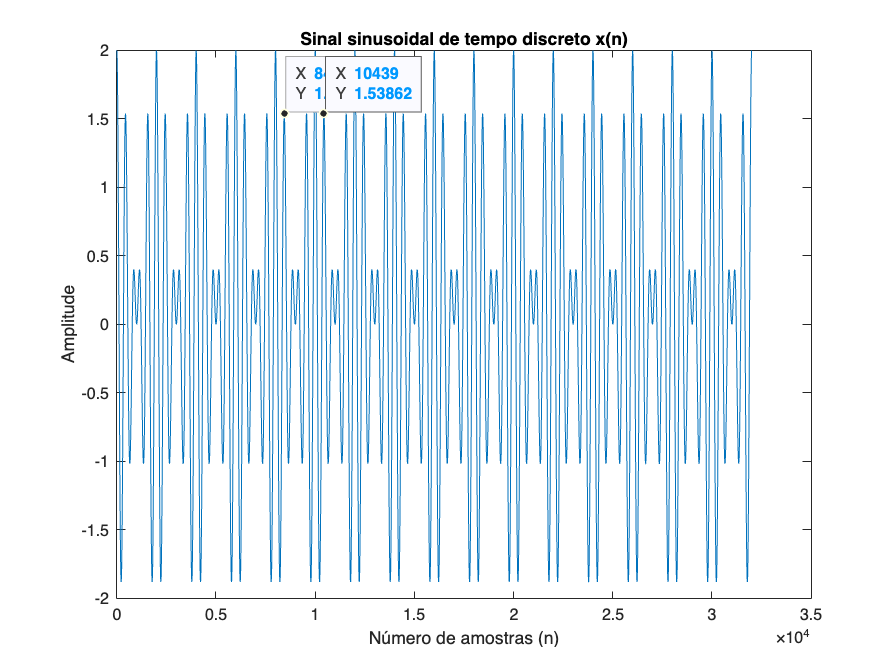

figure;
plot(x)
xlabel('Número de amostras (n)');
ylabel('Amplitude');
title('Sinal sinusoidal de tempo discreto x(n)');

ax2 = gca;
chart2 = ax2.Children(1);
datatip(chart2,8439,1.539);
datatip(chart2,1.044e+04,1.539);

Através das datatips acima obtém-se um período em número de amostras de 2000 (x2-x1=10439-8439), 

Mais uma vez, conclui-se que os períodos em número de amostras, teórico e medido através do gráfico, coincidem.

Ao subamostrar **(é assim que se diz em PT???) **por um fator 3 obtém-se o seguinte **período em amostras** teórico:

y = downsample(x,3);
period_in_samples_y = LCM(theoretical_period, 1/(samplerateQ1/3))*samplerateQ1/3

period_in_samples_y = 2000

Já o período obtido por medição direta:

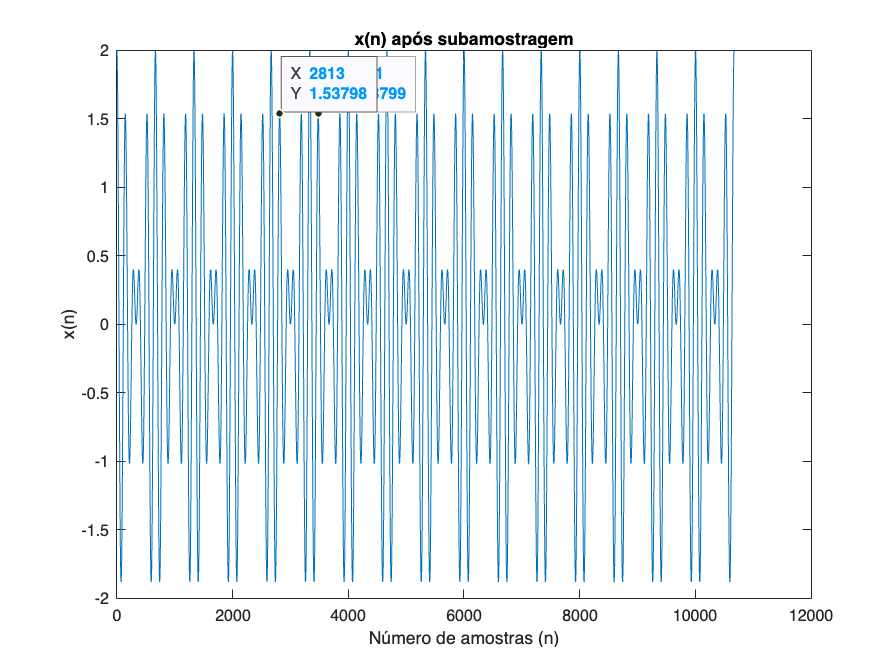

plot(y); 
xlabel('Número de amostras (n)');
ylabel('x(n)');
title('x(n) após subamostragem');

ax3 = gca;
chart3 = ax3.Children(1);
datatip(chart3,3480,1.538);
datatip(chart3,2814,1.538);

Período em amostras através do plot: 2000.

**Q1.3**

A4 = 440; % Hz
function frequency = noteFrequencyFromHalfsteps(no_halfsteps)
    A4 = 440; % Hz
    ratio = 2^(1/12);    
    frequency = A4 * ratio^no_halfsteps;
end

C4 = noteFrequencyFromHalfsteps(-9);
E4 = noteFrequencyFromHalfsteps(-5);
Fs4 = noteFrequencyFromHalfsteps(-3);
G4 = noteFrequencyFromHalfsteps(-2);
B4 = noteFrequencyFromHalfsteps(2);
F4 = noteFrequencyFromHalfsteps(-4);

Use the `seqsin` function to generate a sequence of sinusoids and silence gaps. Create x as the following sequence and listen to the resulting signal:


$$\text{R(0.7), E4(0.25), E4(0.25), F4(0.25), F\#4(0.5), A4(0.25),} \\

\text{F\#4(0.25), A4(0.25), F\#4(0.25), F\#4(0.25), F4(0.25),} \\

\text{E4(0.25), B4(0.25), E4(0.25), E4(0.5), R(0.7)}$$


noteSeq = seqsin(samplerateQ1, 0, 0.7, E4, 0.25, E4, 0.25, F4, 0.25, Fs4, 0.5, A4, 0.25, ...
            Fs4, 0.25, A4, 0.25, Fs4, 0.25, Fs4, 0.25, F4, 0.25, ...
            E4, 0.25, B4, 0.25, E4, 0.25, E4, 0.5, 0, 0.7);
soundsc(noteSeq, samplerateQ1)

**Q1.4**

**É suposto meter as coisas que pede antes de Q1.4?**

samplerate=16e3;
u = @(t) (t >= 0);
t = (-2:1/samplerate:2);

O valor do degrau unitário é nulo para t<0 e ≠0 para t>=0, assim, u(at+b) ≠ 0 para t>=b/a.

se a<0 u(at+b) = u(-t-t0), 

se a>0 u(at+b) = u(t-t0)

ao resolver at+b > 0 , isto é, a condição para que u tome o valor 1, obtemos t > -b/a. Deste modo, 

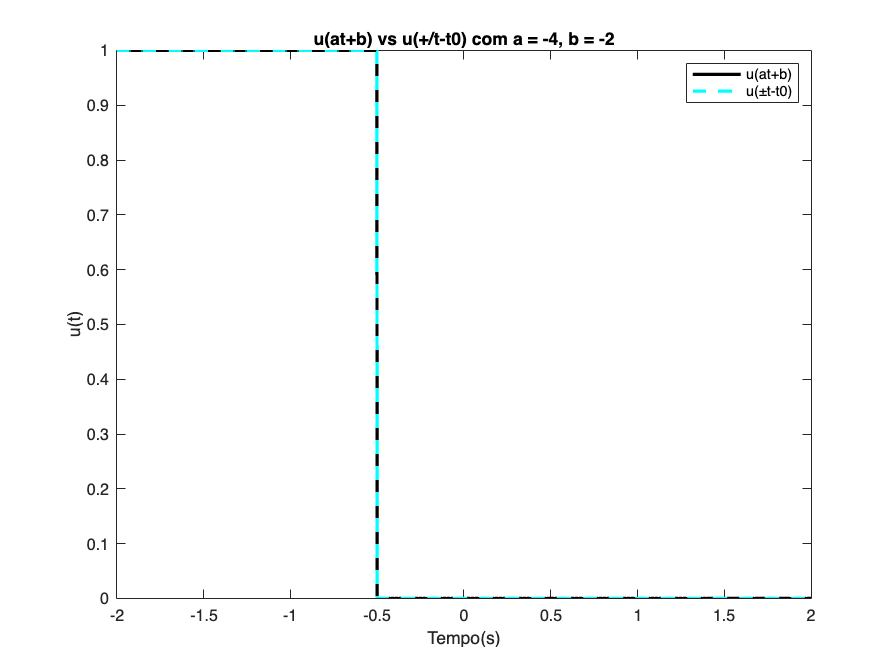

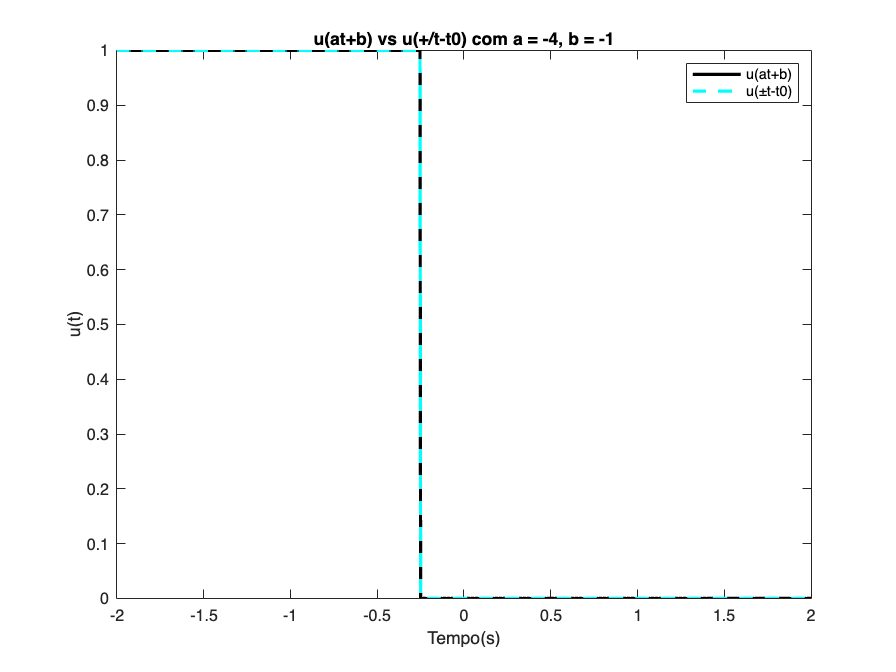

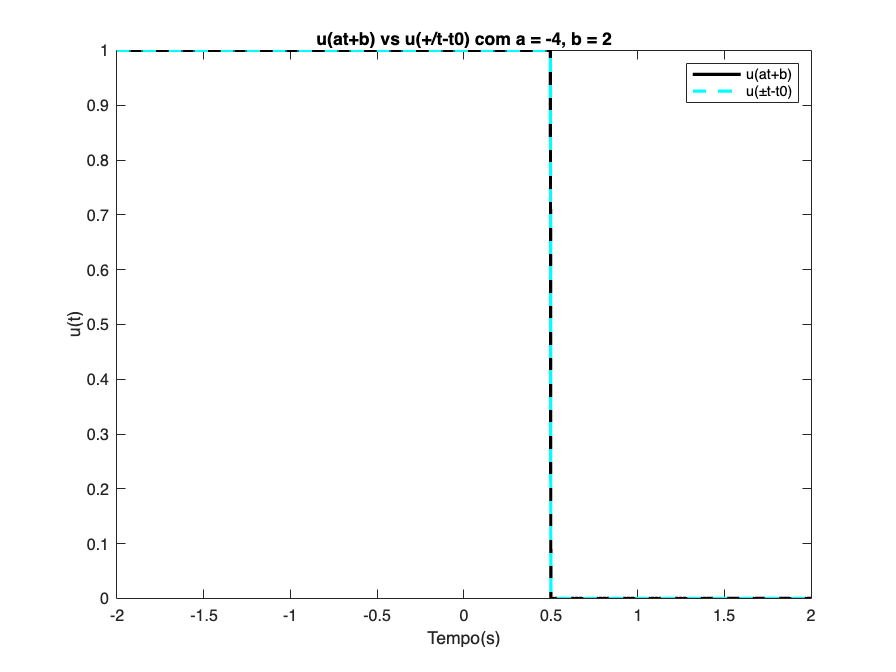

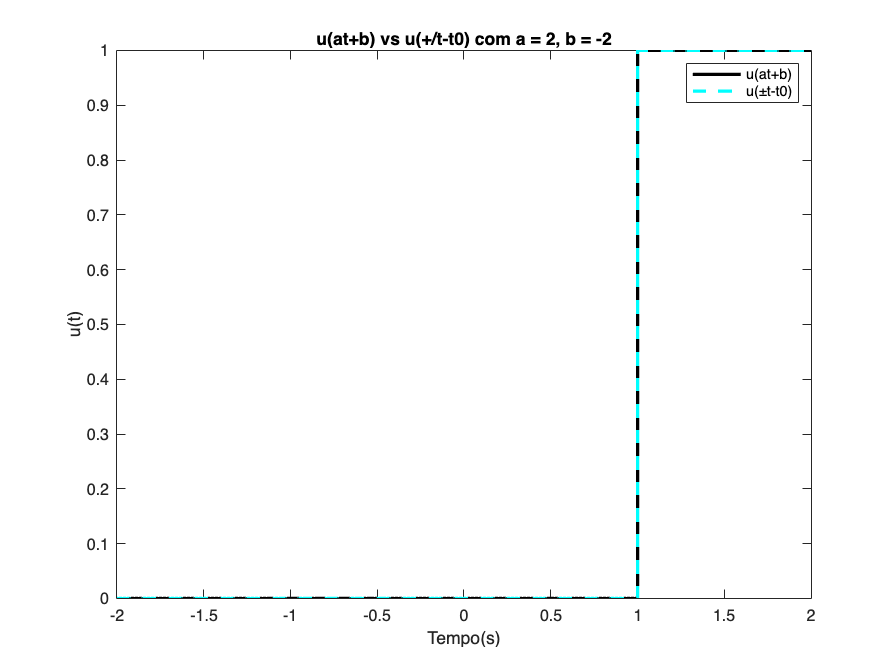

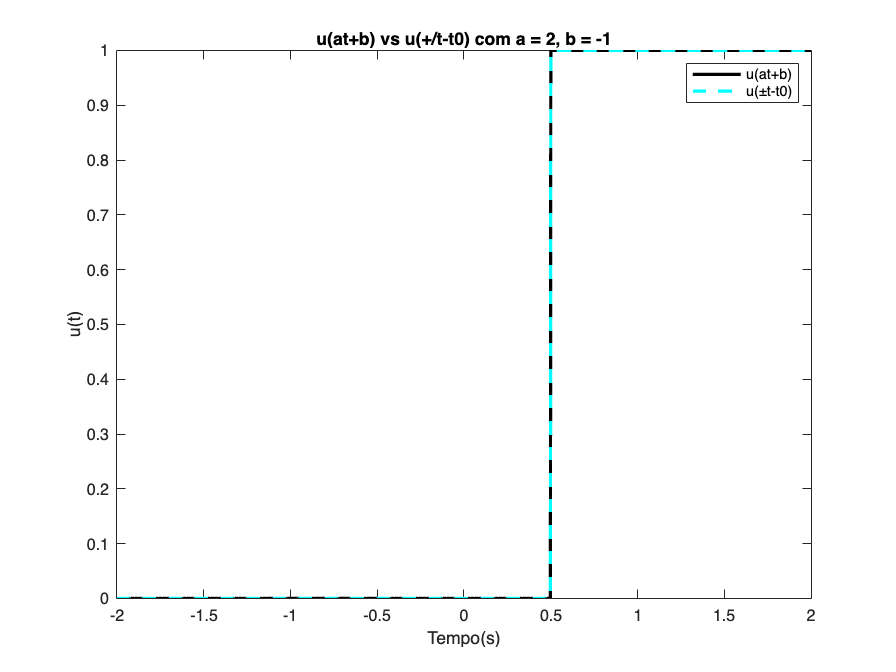

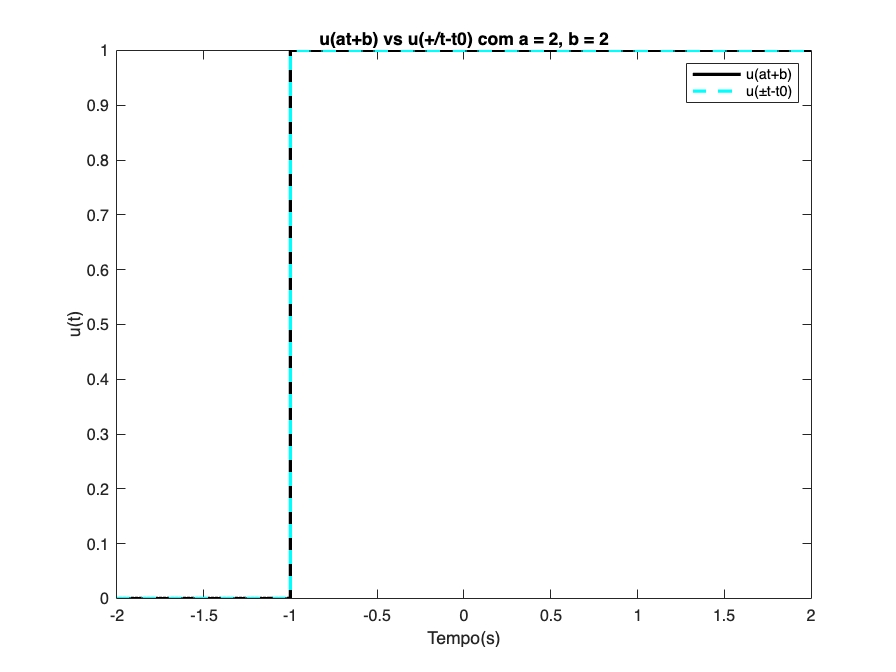

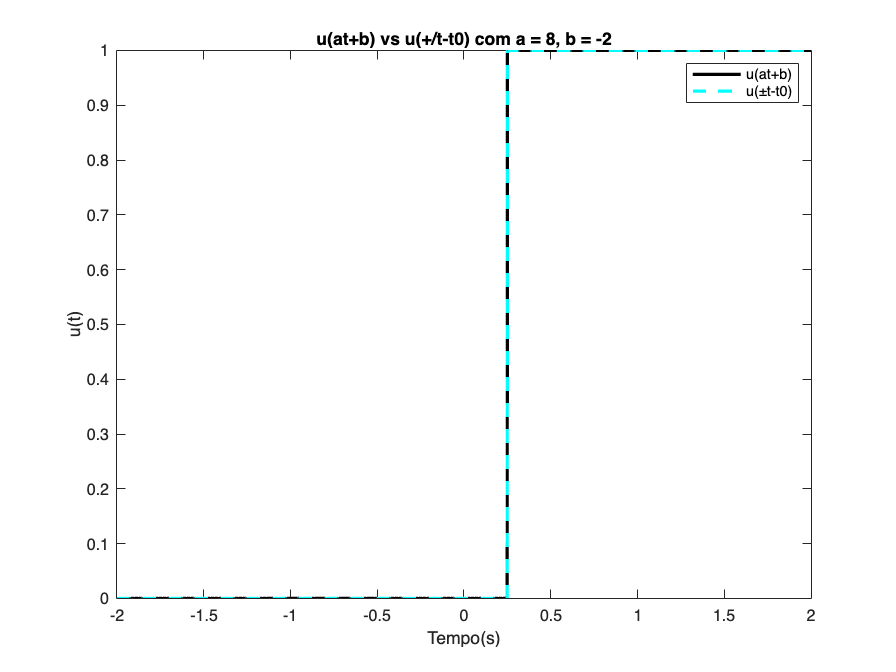

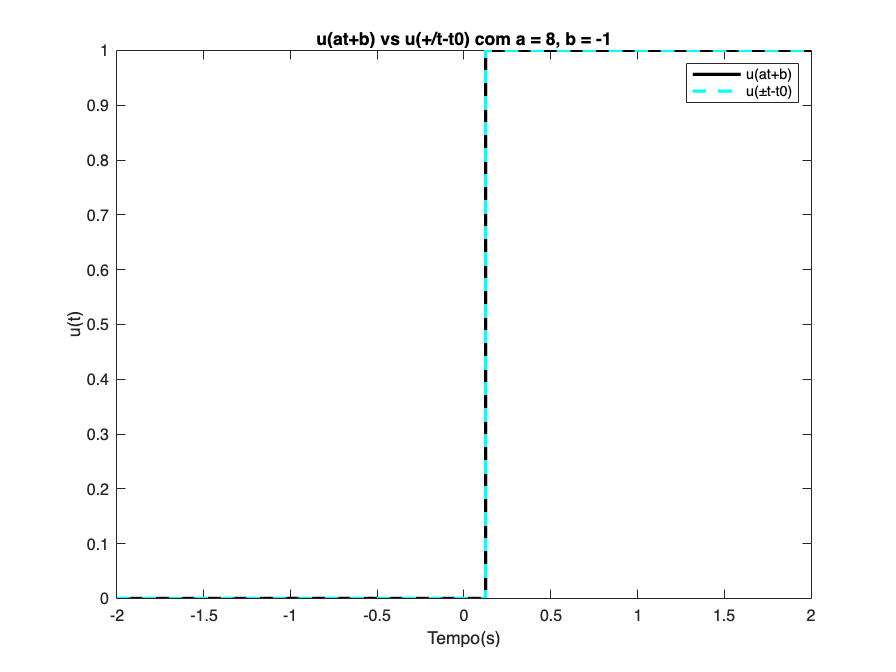

a_values = [-4 2 8];
b_values = [-2 -1 2];

for i = 1:length(a_values)
    for j = 1:length(b_values)
        a = a_values(i);
        b = b_values(j);
        t0 = -b / abs(a); 
        signal_a = sign(a);
       
        step_function_1 = u(a * t + b); 
        step_function_2 = u(signal_a * t - t0); 
        
        figure;
        plot(t, step_function_1,'k', 'LineWidth', 2); hold on;
        plot(t, step_function_2, '--c', 'LineWidth', 2); hold off;
        xlabel('Tempo(s)');
        ylabel('u(t)')
        title(['u(at+b) vs u(+/t-t0) com a = ', num2str(a), ', b = ', num2str(b)]);
        legend('u(at+b)', 'u(±t-t0)')
    end
end

clear;
s = @(t) (t >= 0).*t;                   % Unit ramp
uD = @(t,D) (1/D)*(s(t+D/2)-s(t-D/2));  % Approximate unit step
duD = @(t,D,h) (uD(t+h/2,D)-uD(t-h/2,D))/h; % Numeric derivative
deltaD = @(t,D) duD(t,D,1e-6);          % Approximate unit impulse

O sinal tem valores diferentes de zero entre t0-D/2 e t0+D/2:

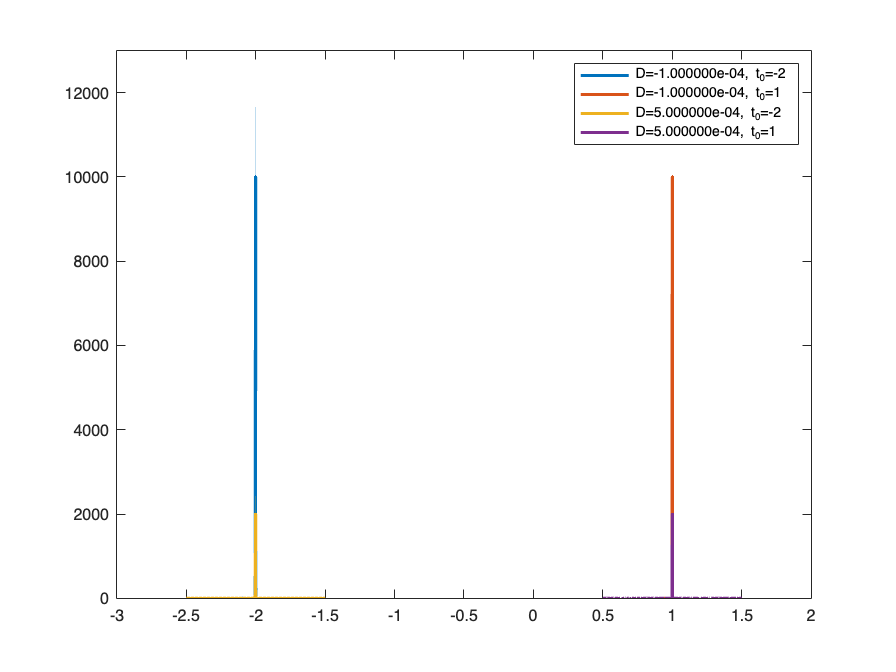

D_values = [-0.0001 0.0005];
t0_values = [-2 1];

figure;
for i = 1:length(D_values)
    for j = 1:length(t0_values) 
    D = D_values(i);
    t0_q1_4 = t0_values(j);
    T = D/2;
    dt=D/1000;
    t2 = t0_q1_4-T-D*1000:dt:t0_q1_4+T+D*1000;
    plot(t2, deltaD(t2-t0_q1_4,D),'LineWidth', 2, 'DisplayName', sprintf('D=%d, t_0=%d', D, t0_q1_4)); hold on
    end
end
hold off;
legend('show');

ylim([0 13000])

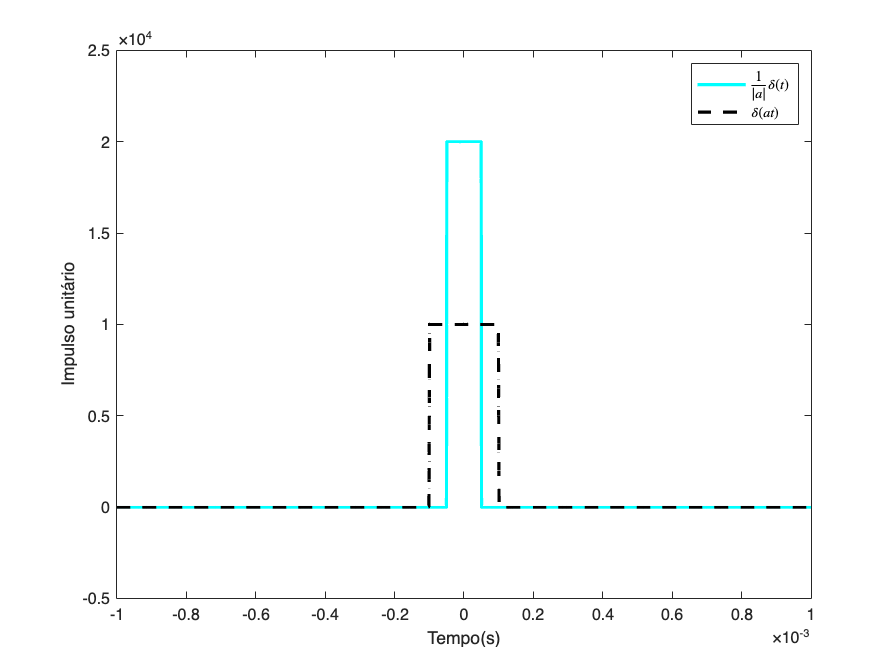

a = 0.5;
D=0.0001;
t3 = (-D*10:D/1000:D*10);

deltaA = (deltaD(t3, D)/abs(a));
figure;
plot(t3, deltaA, "c", "LineWidth",2); hold on
plot(t3,deltaD(a*t3, D) , "k--", "LineWidth",2); hold off
xlabel('Tempo(s)');
ylabel('Impulso unitário');
legend('$\frac{1}{|a|}\delta(t)$', '$\delta(at)$', 'Interpreter', 'latex');

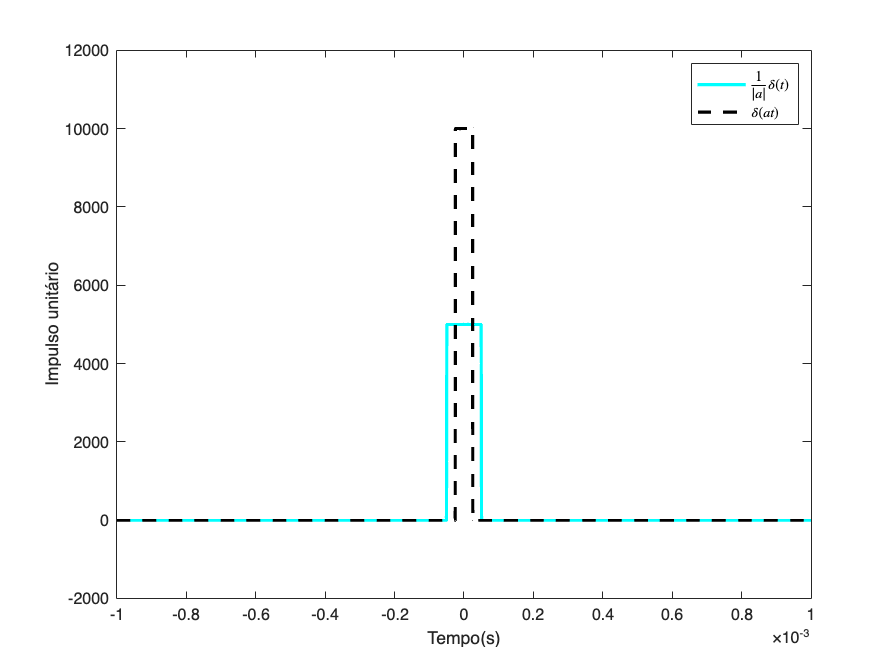

a2 = 2;
deltaA2 = (deltaD(t3, D)/abs(a2));
figure;
plot(t3, deltaA2, "c", "LineWidth",2); hold on
plot(t3, deltaD(a2*t3, D), "k--", "LineWidth",2); hold off
xlabel('Tempo(s)');
ylabel('Impulso unitário');
legend('$\frac{1}{|a|}\delta(t)$', '$\delta(at)$', 'Interpreter', 'latex');

**Q2.1**

system1 = @(x) filter([1 zeros(1,round(0.4*samplerateQ1) - 1) 0.7],1,x);
[x,samplerateQ2] = audioread('echoin.wav');

soundsc([x; system1(x)], samplerateQ2); 

Unrecognized function or variable 'samplerateQ1'.

Error in relatorio>@(x)filter([1,zeros(1,round(0.4*samplerateQ1)-1),0.7],1,x) (line 132)
system1 = @(x) filter([1 zeros(1,round(0.4*samplerateQ1) - 1) 0.7],1,x);


% Em vez de só ouvir o sinal transformado, ouvimos o sinal de entrada 
% antes do sinal de saída - [entrada; saída] -, para poder comparar os dois.

Ao ouvir o resultado da aplicação do sinal lido do ficheiro `echoin.wav` ao sistema `system1`, conseguimos isolar o sinal original, no entanto, ouvimo-lo repetido pouco depois, como que um eco, menos intenso.

Perante o sistema definido, isto faz todo o sentido:

O sistema sobrepõe 2 sinais: o sinal de entrada e uma transformação do sinal de entrada pesado por uma constante. Nesta última parcela, ao usar uma constante $<1$, o sinal é atenuado e, com a transformação na variável independente, é ainda atrasado. Estes dois fenómenos faz com que, ao sinal de entrada, estejamos a somar algo que simule o seu eco.

**Q2.2**

A figura parece representar uma sobreposição de inúmeros impulsos com diferentes atrasos, que diminuem progressivamente  ($\sum\limits_i a_i \cdot\delta(t-t_{0_i})$), com $a_{i+1}$ aproximadamente menor que $a_i$). 

Por isto, observamos menos impulsos mais fortes para atrasos pequenos, e mais impulsos mais fracos para atrasos maiores.

Este padrão ocorre devido ao comportamento físico do sinal numa sala como a descrita. Ao ser emitido pela fonte, o sinal reflete-se nas paredes, onde é parcialmente absorvido e atenuado a cada reflexão. Assim, o sinal muda de direção e perde intensidade ao longo do tempo. Quanto mais reflexões o sinal sofre, maior distância percorre e, consequentemente, maior é o atraso antes de atingir o recetor.

Inicialmente, para atrasos pequenos, há menos impulsos porque o sinal segue caminhos diretos e curtos até ao recetor. Estes caminhos envolvem menos reflexões, resultando em menor atenuação. Com o passar do tempo, as frentes de onda que seguiram caminhos mais indiretos, sofrendo múltiplas reflexões, começam a chegar ao recetor. Estes sinais percorreram distâncias maiores e foram mais atenuados, o que resulta em impulsos mais fracos com atrasos maiores. São mais impulsos pois há muitas direções diferente das "ótimas", que levam aos caminhos mais curtos.

Assim, a resposta ao impulso reflete a distribuição das trajetórias que o sinal percorre.

**Q2.**

% posição 3d do receiver
mic = [1 2 1];
n = 12;
% refletividade das paredes
r = 0.7;
% dimensões da sala
rm = [10 10 3];
% posição 3D da source
src = [5 5 1];
h = rir(samplerate, mic, n, r, rm, src);

[x,samplerate] = audioread('echoin.wav');
y = conv(h,x);
soundsc(y,samplerate)

**Q2.3**

load fingerprint.mat

%dimensões da sala
rm_now = [20 15 10];
%refletividade das paredes de madeira
r_wood = 0.6;
%refletividade das paredes de betão
r_concrete = 0.9;

%fonte localizada a 1m de altura, distância horizontal desconhecida.
%Possíveis coordenadas para o recetor a 3m e a 20m da fonte
src_3 = [-2 2 1];
src_20 = [1 22 1];

%paredes de madeira com o recetor a 3m de distância
h_wood_3 = rir(samplerate, mic, n, r_wood, rm_now, src_3);
%paredes de madeira com o recetor a 20m de distância
h_wood_20 = rir(samplerate, mic, n, r_wood, rm_now, src_20);
%paredes de betão com o recetor a 3m de distância
h_concrete_3 = rir(samplerate, mic, n, r_concrete, rm_now, src_3);
%paredes de betão com o recetor a 20m de distância
h_concrete_20 = rir(samplerate, mic, n, r_concrete, rm_now, src_20);

%saída/convolução de cada hipótese 
y_wood_3 = conv(x, h_wood_3);
y_wood_20 = conv(x, h_wood_20);
y_concrete_3 = conv(x, h_concrete_3);
y_concrete_20 = conv(x, h_concrete_20);

%input
soundsc(x, samplerate);
pause(7);
%output
soundsc(y, samplerate);
%pausa para não sobrepor os sons
pause(7);

%sons produzidos nas diferentes hipóteses:
soundsc(y_wood_3, samplerate); 
pause(7);
soundsc(y_wood_20, samplerate);    
pause(7);
soundsc(y_concrete_3, samplerate);  
pause(7);
soundsc(y_concrete_20, samplerate); 

Ao ouvir os sons conclui-se que as paredes de concreto levam a um maior eco o que é esperado tendo em conta  o seu maior índice de refletividade, enquanto que uma maior distância leva a um maior atraso na receção do som. Desta forma, conclui-se que o mais provável é que a fonte esteja localizada a uma distância de 3 metros do recetor e as paredes da sala serão de betão (*concrete*).

Visto que esta é uma análise subjetiva, sujeita a erros, optamos por vizualisar o plot produzido através de cada uma das hipóteses de modo a confirmar as observações retiradas da audição dos diferentes sons.

MAYBE MADEIRA A 20M NOT SUREEEE

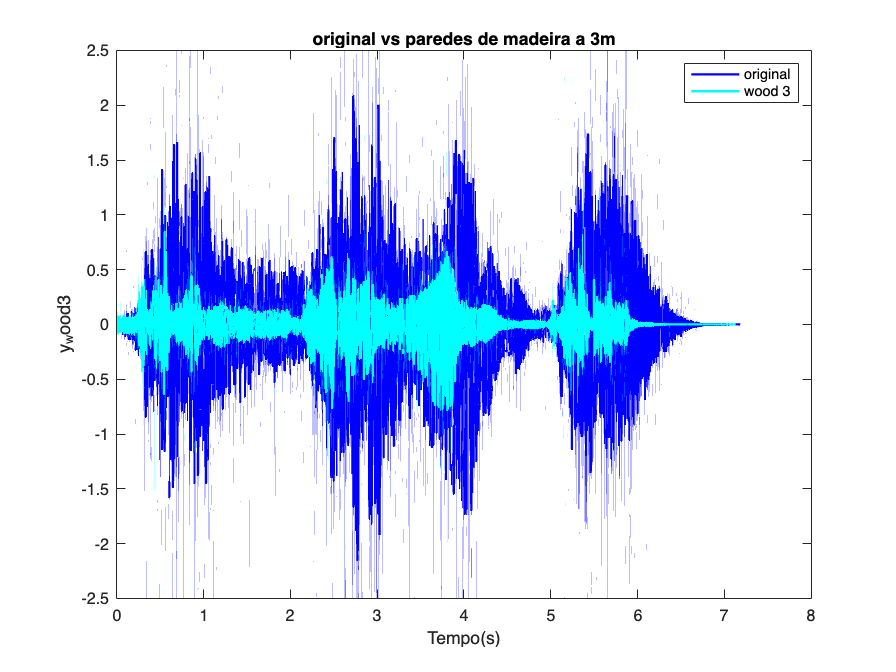

ty = (0:length(y)-1)/samplerate;
tyw3 = (0:length(y_wood_3)-1)/samplerate;
tyw20 = (0:length(y_wood_20)-1)/samplerate;
tyc3 = (0:length(y_concrete_3)-1)/samplerate;
tyc20 = (0:length(y_concrete_20)-1)/samplerate;
figure;
plot(ty, y,'b', 'LineWidth', 1.5); hold on
plot(tyw3, y_wood_3, 'c', 'LineWidth', 1.5); hold off
xlabel('Tempo(s)')
ylabel('y_wood3')
title("original vs paredes de madeira a 3m");
legend('original', 'wood 3');

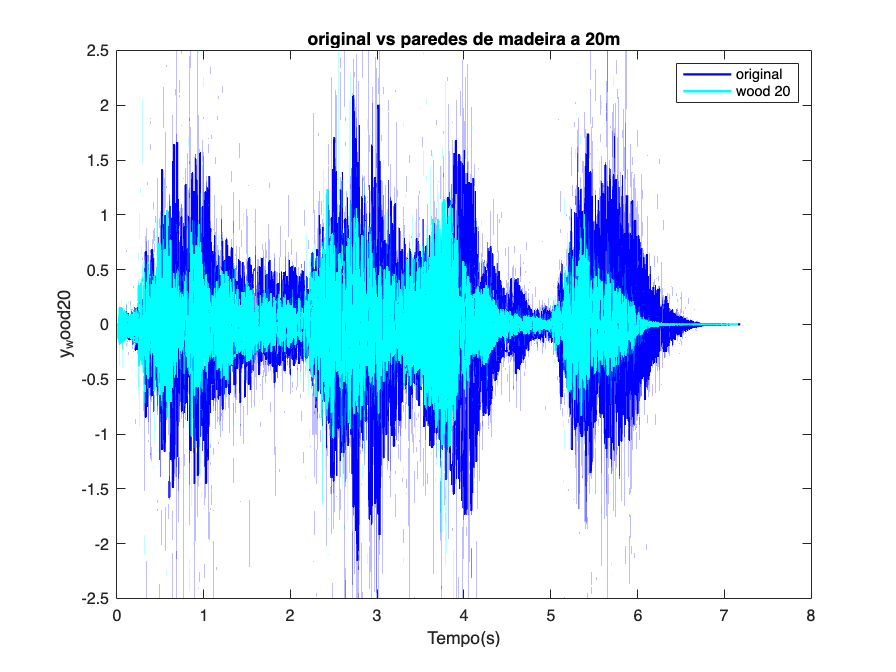

plot(ty, y,'b', 'LineWidth', 1.5); hold on
plot(tyw20, y_wood_20,'c', 'LineWidth', 1.5); hold off
xlabel('Tempo(s)')
ylabel('y_wood20')
title("original vs paredes de madeira a 20m");
legend('original', 'wood 20');

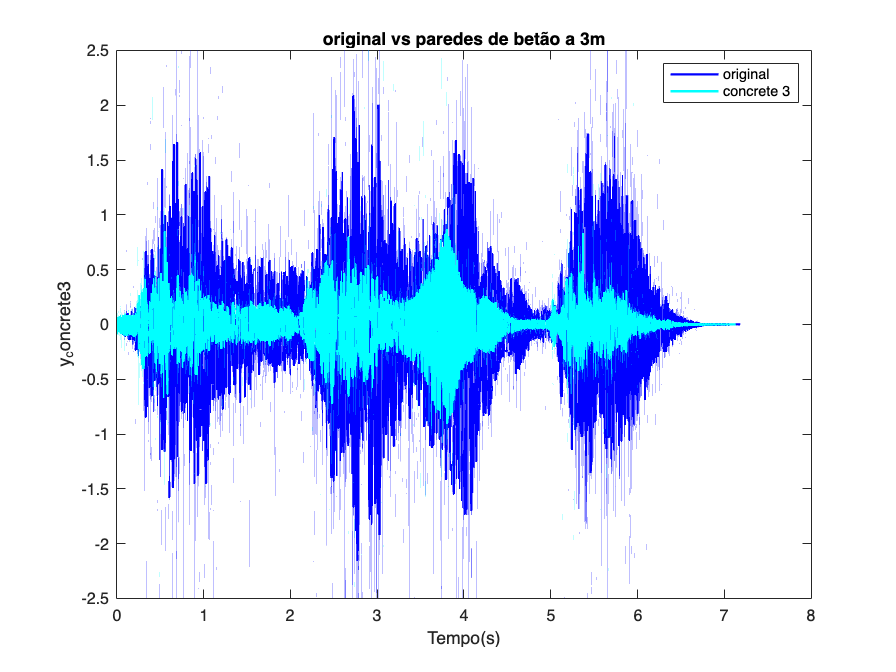

plot(ty, y,'b', 'LineWidth', 1.5); hold on
plot(tyc3, y_concrete_3, 'c', 'LineWidth', 1.5); hold off
xlabel('Tempo(s)')
ylabel('y_concrete3')
title("original vs paredes de betão a 3m");
legend('original', 'concrete 3');

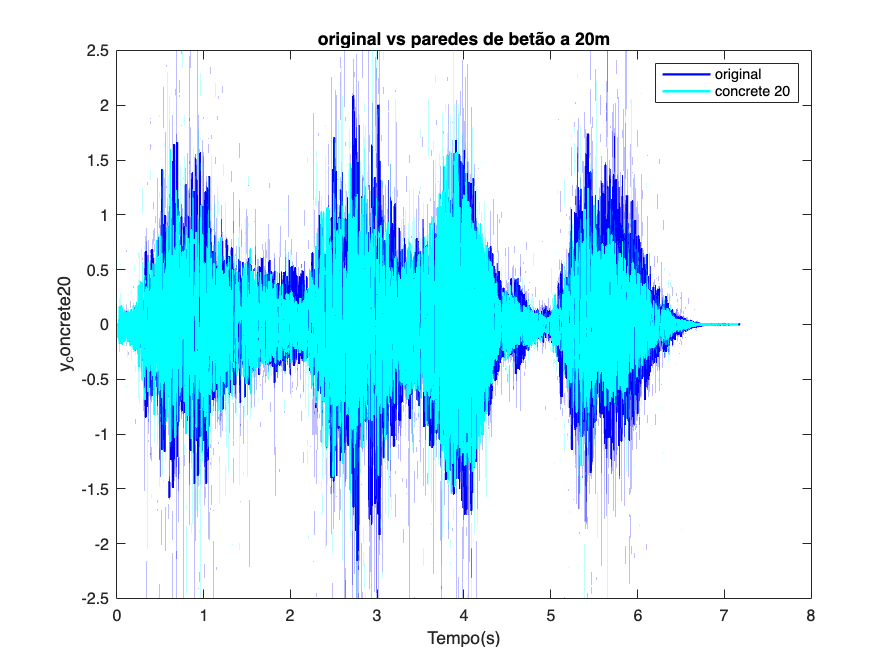

plot(ty, y,'b', 'LineWidth', 1.5); hold on
plot(tyc20, y_concrete_20, 'c', 'LineWidth', 1.5); hold off
xlabel('Tempo(s)')
ylabel('y_concrete20')
title("original vs paredes de betão a 20m");
legend('original','concrete 20');

**Q2.4**

system1 = @(x) filter([1 zeros(1,round(0.4*samplerate) - 1) 0.7],1,x);
samplerate = 16e3;
t = (-4:1/samplerate:4);
%valor fornecido pela docente
omega = 27;
x1 = cos(omega*t);
y1 = system1(x1);

% Parametros do sistema 1
deslocamento = 0.4; 
escalamento = 0.7;

% Amplitude e fases teóricos para Acos(omega*t+phi). Demonstração abaixo
A = sqrt(1 + escalamento^2 + 2 * escalamento * cos(-omega * deslocamento))
phi = atan2(escalamento * sin(-omega * deslocamento), 1 + escalamento * cos(omega * deslocamento))

y1_teorico = A * cos(omega * t + phi);
%plot do sinal obtido pelo sistema1
plot(t, y1, 'r', 'LineWidth', 1.5); hold on;
%plot do sinal previsto (Acos(omega*t+phi))
plot(t, y1_teorico, 'k--', 'LineWidth', 1); hold off;
title('Resposta ao sistema 1: y1(t) vs Sinal previsto (teórico)');
xlabel('Tempo (s)');
ylabel('Amplitude');
legend('Output do sistema: y1(t)', 'Sinusoide previsto');
grid on;

**Q2.5**

## Linearidade

function test_linearity(t, x1,x2, a)
    s2_x1x2 = system2(a*(x1+x2),t);
    s2_x1_s2_x2 = a*system2(x1,t) + a*system2(x2,t);
    
    disp("S2(a(x1+x2)) (blue) vs a*S2(x1)+a*S2(x2) (green)")
    plot(t, s2_x1x2); hold on;
    plot(t, s2_x1_s2_x2, "g--"); hold off
end

t = -10:10;
x1 = deltaD(t-1,1);
x2 = -3*deltaD(t-2,1);
a=17;

test_linearity(t, x1, x2, a)

x1 = uD(t-4, 1);
x2 = -uD(t+1, 1);
a = 3

test_linearity(t, x1, x2, a)
t=-40:40
x1 = cos(t) + sin(t);
x2 = cos(t-1) + sin(t-5);
a = 20;
test_linearity(t, x1, x2, a)

Ao testar sinais fundamentais na construção de outros sinais, mas todos diferentes - um impulso, um degrau unitário e um $cos$, observámos sempre um comportamento linear. 

Computacionalmente, não nos é possível testar o espaço todo de sinais de entrada - já que este é infinito. No entanto, uma vez que os sinais que nós testámos poderiam ser usados para construir qualquer sinal de entrada neste espaço de sinais, através de deslocamentos no tempo e combinações lineares, estamos bastante confiantes de que se trata de um sistema linear.

Há que reforçar que não podemos constatar com certeza a linearidade, só podemos comentar os exemplos que observámos. (Exemplo: se, para t=1000, o sistema não for linear, tal não estaria incluído nos nossos testes. Como não temos modo de criar uma suite de testes absolutamente exaustiva, não podemos generalizar a nossa conclusão.)

## Invâriancia no Tempo

function test_timeInvariance(t, t0, x)
    x_t = x(t);
    x_t_t0 = x(t-t0);
    y_t_t0 = system2(x_t, t);
    S2_x_t_t0 = system2(x_t_t0, t);

    font_s = 16;

    plot(t, S2_x_t_t0, "r"); hold on; plot(t+t0, y_t_t0, "b--"); hold off; 
    xlim([-10 10]); ylim([-0.2 1.2]);
    xlabel('t', 'FontSize', font_s, 'Interpreter', 'latex');
    ylabel('$S(x(t))$', 'FontSize', font_s, 'Interpreter', 'latex');
    title('\fontsize{16} {\color{red}S(x(t-t0)) \color{black} vs \color{blue}y(t-t0)}')
end

t = -10:10;
x1 = @(t) deltaD(t-1,1);

test_timeInvariance(t, 2, x1)
test_timeInvariance(t, 3, x1)

Com um exemplo, vemos que o sinal não é invariante no tempo.

Nestes gráficos, vemos a sobreposição de 2 casos.

Em vermelho, vemos o resultado da aplicação do `system2` num sinal `x` que foi deslocado no tempo. Em azul, vemos o resultado, deslocado no tempo, da aplicação do `system2 num sinal x`.

No primeiro gráfico, o deslocamento no tempo é de 2 unidades, ao passo que, no segundo, é de 3. Como podemos ver, no segundo gráfico os sinais obtidos não são equivalentes, o que nos diz que o sistema não pode ser invariante no tempo - se pudesse, os sinais seriam iguais independentemente do deslocamento temporal.

## Memória e Causalidade

function test_memory_or_causality(t, x1, x2, t0)
    % Let x1 and x2 be 2 similar signals which we will evaluate at point t0.
    % In constructing them, we should make them essentially the same, but
    % different only at some point t1≠t0.
    % If the output signal at t0 changes, then the system has memory.

    S2_x1 = system2(x1, t);
    S2_x2 = system2(x2, t);
    
    font_s = 16;

    figure;
    plot(t, x1, "r"); hold on; plot(t, x2, "g--"); xline(t0, 'k--', 'LineWidth', 1.5); hold off;
    xlim([-10 10]); ylim([-1.5 1.5]);
    xlabel('t','FontSize',font_s, 'Interpreter','latex'); ylabel('$x(t)$', 'FontSize',font_s, 'Interpreter','latex');
    title("Input signals: $\texttt{x1}$ in red, $\texttt{x2}$ in green", 'Interpreter','latex', 'FontSize', font_s);    
    

    figure;
    plot(t, S2_x1, "r"); hold on; plot(t, S2_x2, "g--"); xline(t0, 'k--', 'LineWidth', 1.5); hold off;
    xlim([-10 10]); ylim([-1.5 1.5]);
    xlabel('t','FontSize',font_s, 'Interpreter','latex'); ylabel('$S(x(t))$', 'FontSize',font_s, 'Interpreter','latex');
    title("Output signals: $S(\texttt{x1})$ in red, $S(\texttt{x2})$ in green", 'Interpreter','latex', 'FontSize', font_s);    

end


x1 = deltaD(t-4,1) + deltaD(t-3,1) - deltaD(t+4,1);
x2 = deltaD(t-3,1) - deltaD(t+4,1);
t0 = -4;

test_memory_or_causality(t, x1, x2, t0)

Por contra-exemplo, demonstramos que o sistema tem memória, e que não é causal: ao alterarmos o sinal de entrada num ponto t1=4 diferente do ponto t0=-4, e inclusive após deste, a saída do sistema altera-se nesse ponto t0=4, ou seja, a saída num ponto no tempo depende da entrada noutro ponto no tempo - cumprindo a definição de memória de um sistema -, ponto este que é posterior no tempo ao inicial - violando a definição de causalidade de um sistema.

## Estabilidade

function test_stability(t, uD)
    x1 = sin(t)
    x2 = uD(t,1)
    x3 = exp(-abs(t))
    plot(t, system2(x1,t), "g-"); hold on; plot(t, system2(x2,t), "r-"); hold on; plot(t, system2(x3,t), "c"); hold off; ylim([-1 1.5]);
end
test_stability(-10:10, uD)

Nos testes feitos, podemos ver que, para sinais limitados, a saída do sistema também se mantém limitada. Observamos, inclusive, que o sinal de saída se mantem entre os mesmos limites que o sinal de entrada. Por este motivo, acreditamos que o sistema será estável. Não podemos, no entanto, garantir que este comportamento se verifique para qualquer sinal que apliquemos ao sistema, portanto é uma hipótese que não podemos garantir com 100% de confiança.

## Invertibilidade

Das nossas experiências com o sistema, parece que este é o seu próprio sistema inverso. Sendo assim, tanto quanto pudemos validar, o sistema é invertível. Não podemos afirmar isto de um modo universal, já que não conseguimos testar qualquer sinal de entrada, e é possível que o sistema tenha comportamentos que não pudemos observar.

plot(t, system2(system2(x1, t), t), "g-"); hold on; plot(t, x1, "r--"); hold off;

**Q3.1**

t = (-5:1/samplerate:5)';
function xN = approx_x(T, T1, N, t)
    w0 = 2*pi/T;
    ak = @(k) (2*T1/T).*sin(k*w0*T1)./(k*w0*T1);
    a0 = 1/2; % Segregate a0, which often has a different expression
    xN = exp(1i*w0*t*(-N:N))*[ak(-N:-1) a0 ak(1:N)].';
end

T = 1;
T1 = 1/4;
Ns = [1 2 3 4 5 10 100 ];
colors = lines(length(Ns));

for i = 1:length(Ns)
    N = Ns(i);
    x = approx_x(T, T1, N,t);
    figure('Units', 'pixels', 'Position', [0, 0, 1000, 500]); 
    plot(t, real(x), 'Color', colors(i, :), 'DisplayName', char(compose('N = %d', N))); hold on;
end
hold off; grid; legend

Os detalhes da forma do sinal demonstram que a SFC é convergente pois verifica-se que é absolutamente integrável tem um número finito de máximos e mínimos num período e um número finito de descontinuidades num intervalo de tempo finito.

Para além disto à medida que aumentamos N (ou seja, aproximando o nosso somatório da verdadeira série), vemos que a forma do nosso sinal se aproxima da de uma onda quadrada.

%spectra: representação do sinal no domínio da frequência
% mostar 2 imagens side by side: 1 aproximada e outra auto
xN = approx_x(T, T1, 100, t);
[XN, f] = cftransform(xN, length(t)/2+1, length(t), samplerate);
figure;
plot(f, abs(XN)); grid on; ylim([-0.01 0.15]); xlim([-10 140]);%samplerate/2]);
title('Spectra');
figure;
plot(f, angle(XN)); grid on
title('Angulo')
figure;
plot(f, real(XN));grid on
title('Re(XN)');
figure;
plot(f, imag(XN));grid on
title('Im(XN)');

**Q3.2 **

Ns = Ns(1:5)
colors = cool(length(Ns))
for i = 1:length(Ns)
    N = Ns(i);
    xN = approx_x(T, T1, N, t);
    [XN, f] = cftransform(xN, length(t)/2+1, length(t), samplerate);
    figure;
    plot(f, abs(XN), 'Color', [colors(i, :) 0.5], 'DisplayName', char(compose('N = %d', N))); 
    grid on; ylim([-0.01 0.4]); xlim([-5 10]); %samplerate/2]);
    title('Spectra of Finite Fourier Sums with different Ns');legend
end

**Q3.3**

**Q4.2**

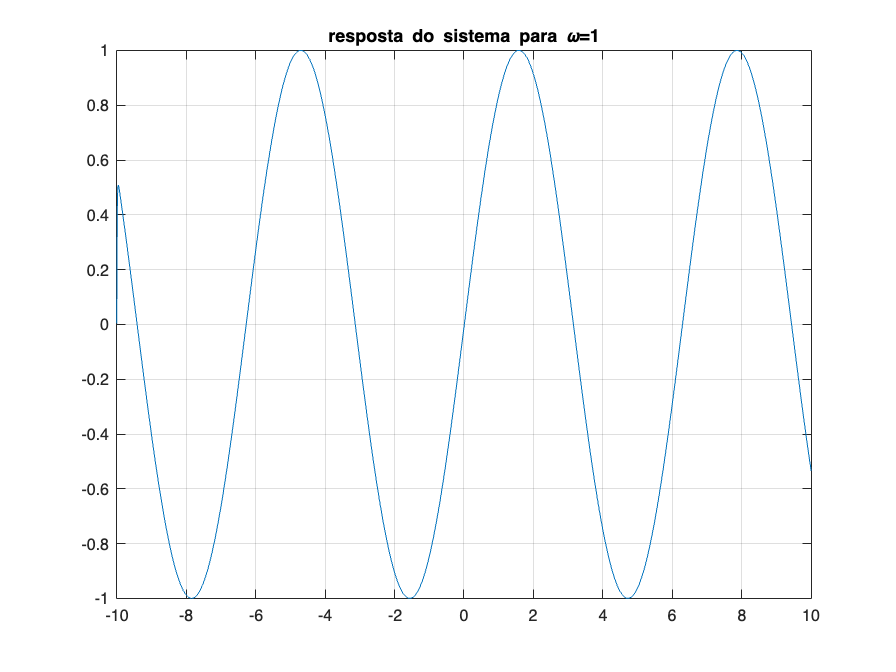

moduloH =     0.9999         0         0         0         0         0


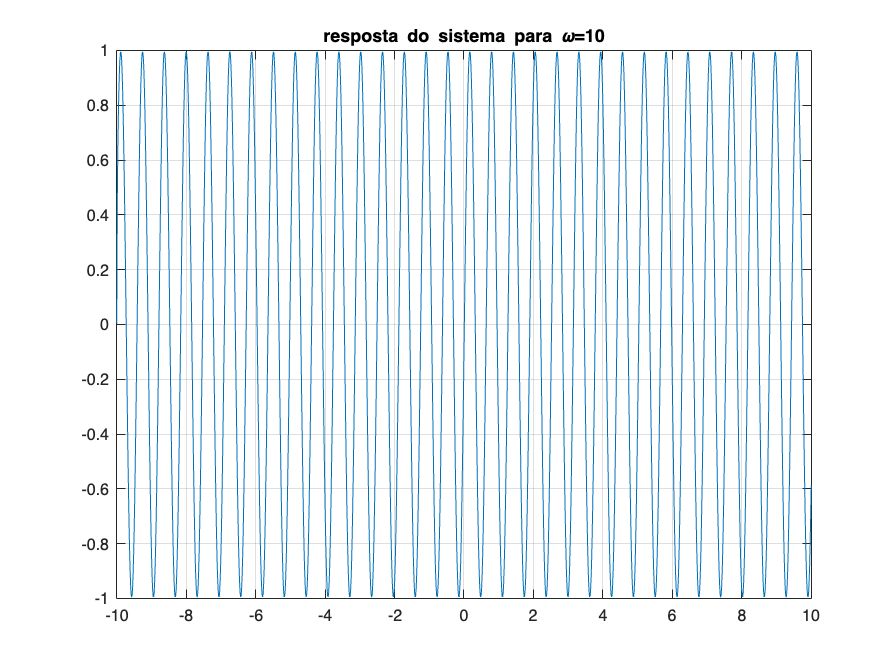

moduloH =     0.9999    0.9950         0         0         0         0


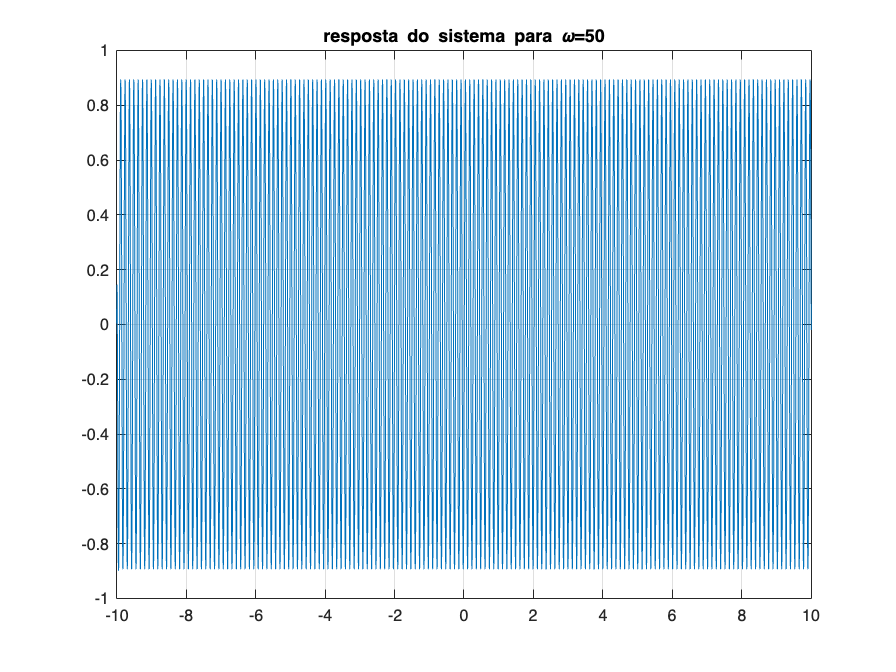

moduloH =     0.9999    0.9950    0.8939         0         0         0


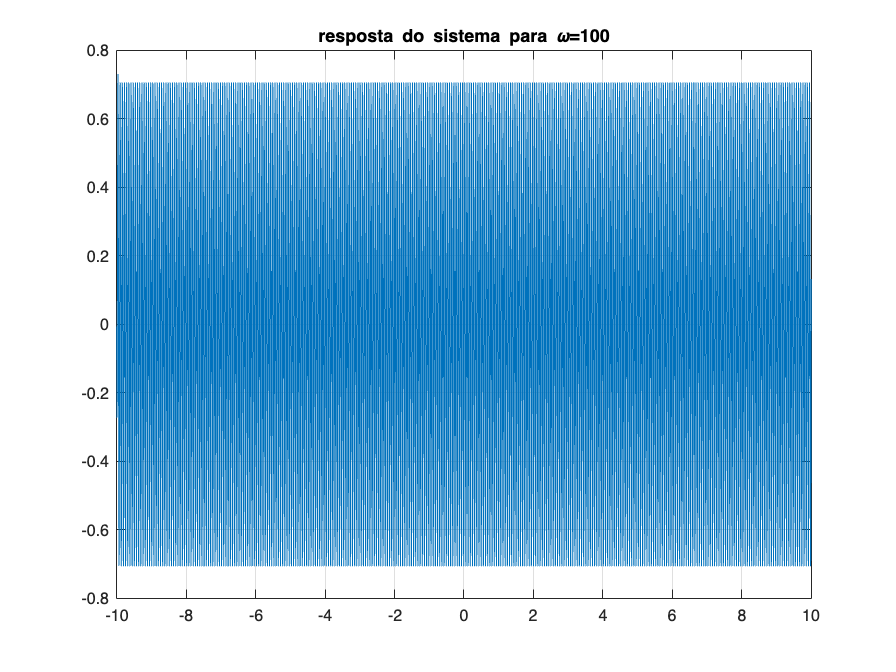

moduloH =     0.9999    0.9950    0.8939    0.7060         0         0


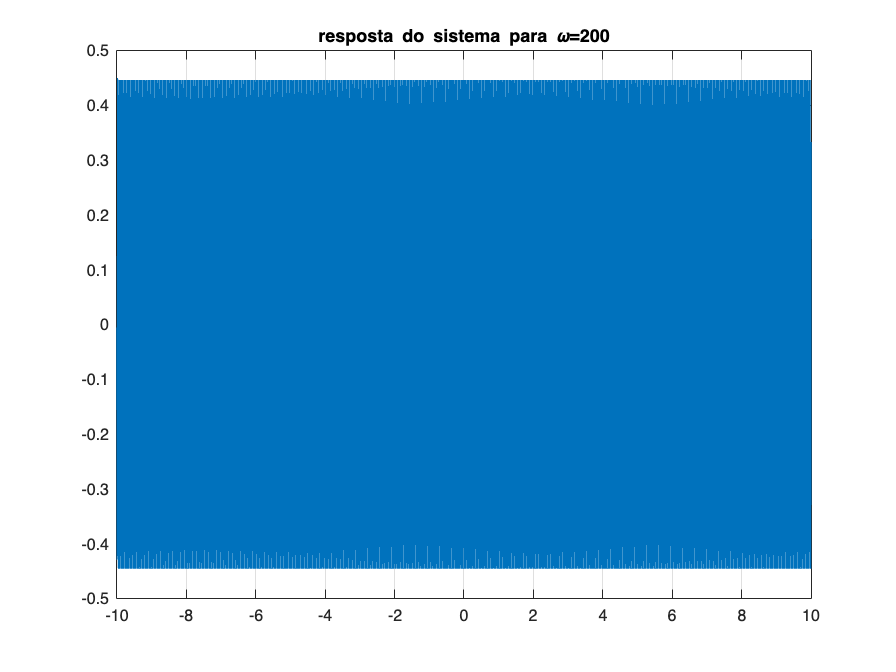

moduloH =     0.9999    0.9950    0.8939    0.7060    0.4461         0


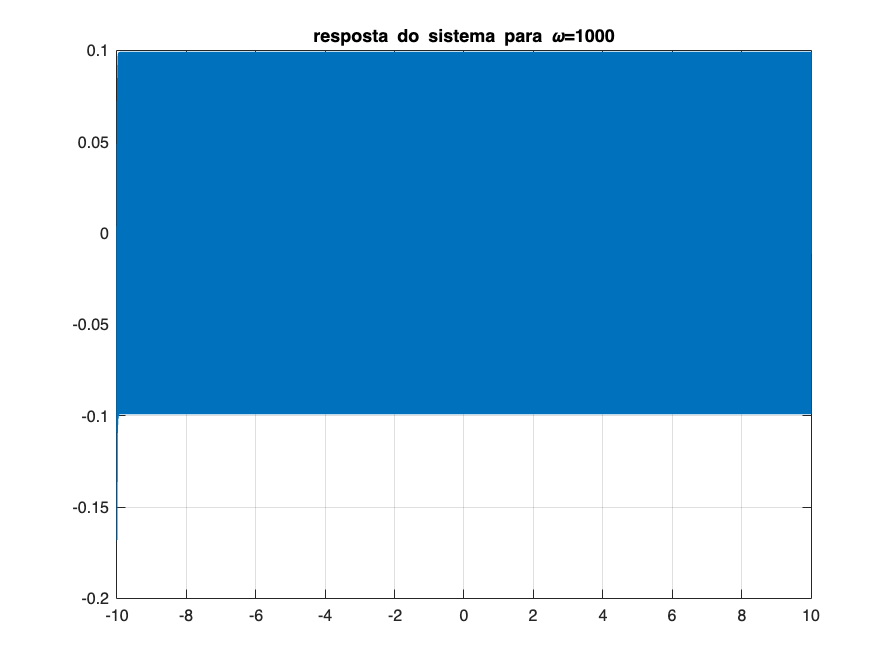

moduloH =     0.9999    0.9950    0.8939    0.7060    0.4461    0.0992


samplerate = 16e3;
t = (-10:1/samplerate:10);
omega = [1, 10, 50, 100, 200, 1000];
moduloH = zeros(size(omega));

for i=1:length(omega)
    %rad/s para Hz
    f = omega(i)/(2*pi);
    %sinal sinusoidal
    x=sin(omega(i)*t);
    %resposta do sistema e plot
    y=system3(x,samplerate);
    figure;
    plot(t,y); grid on
    title("resposta do sistema para \omega="+ num2str(omega(i)));

    % para evitar "trasient effects" nas extremidades da variável do tempo
    intervalo_estavel = t>-5 & t<5;
    y_estavel = y(intervalo_estavel);
    % máximo ao mínimo-->2vezes a amplitude
    A = max(abs(y_estavel)) - min(abs(y_estavel)); 
    moduloH(i) = A
end

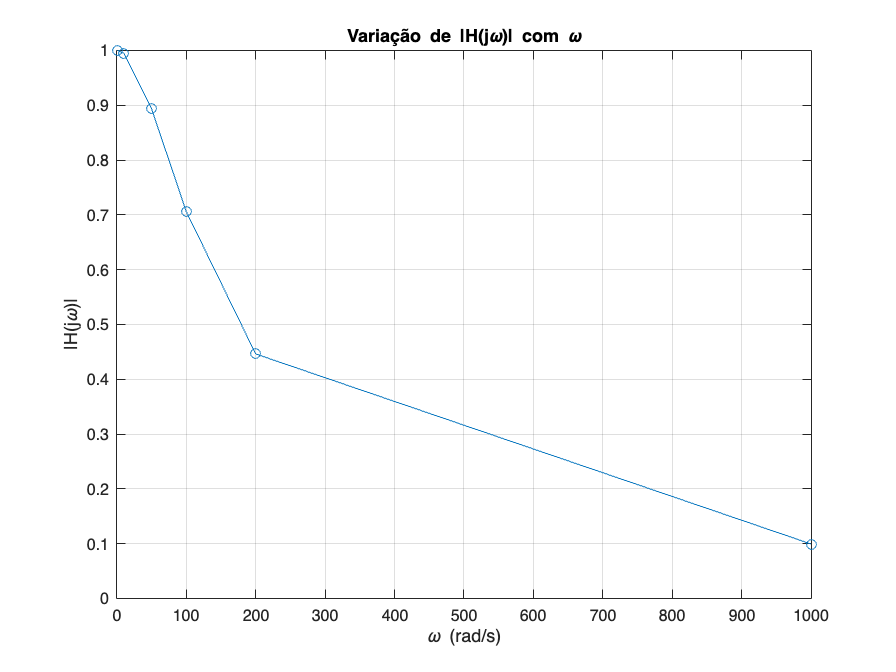

%plot da variação do módulo de H(jw) com a frequência angular
figure;
plot(omega, moduloH, 'o-');
title('Variação de |H(j\omega)| com \omega');
xlabel('\omega (rad/s)');
ylabel('|H(j\omega)|');
grid on;

%Tipo de filtro:
if moduloH(1) > moduloH(end)
    disp('Filtro passa-baixo');
elseif moduloH(1) < moduloH(end)
    disp('Filtro passa-alto');
else
    disp('Filtro passa-banda');
end

Filtro passa-baixo


Verifica-se assim que se trata de um filtro passa-baixo uma vez que o módulo da resposta em frequência diminui com o aumento da frequência angular.

**Q4.3**

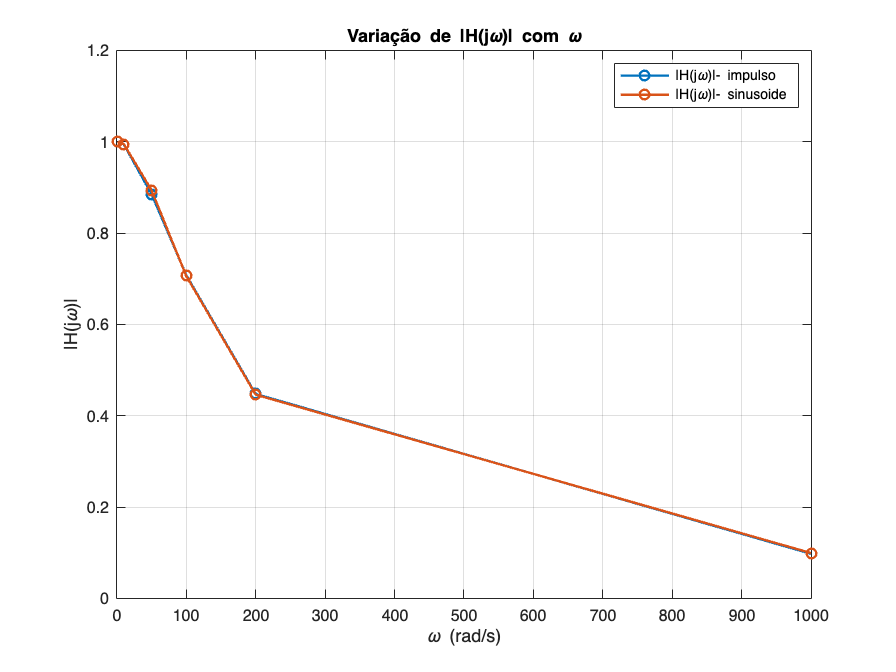

t = (-0.2:1/samplerate:1)';
x = deltaD(t,10/samplerate);
% aproximação da resposta ao impulso
h = system3(x,samplerate);
% TFTC da resposta ao impulso --> resposta em frequência (integral -oo a
% +oo h(t)e^-jwt dt)

Delta_t = 1/samplerate;
% transformada de fourier da resposta ao impulso
H = fftshift(fft(h)) * Delta_t;       
eixoFreq = linspace(-samplerate/2, samplerate/2, length(t));
eixoOmega = 2*pi*eixoFreq;             
Hjw = zeros(size(omega));
for i = 1:length(omega)
    [~, indices] = min(abs(eixoOmega - omega(i)));
    Hjw(i) = abs(H(indices));
end

figure;
plot(omega, Hjw, 'o-','LineWidth',1.5); hold on;
xlabel('\omega (rad/s)');
ylabel('|H(j\omega)|');
title('Variação de |H(j\omega)| com \omega');
plot(omega, moduloH, 'o-','LineWidth', 1.5);
legend('|H(j\omega)|- impulso', '|H(j\omega)|- sinusoide')
grid on

% Primeiro método de computação da constante de tempo: para o tempo
% positivo (indice~t=0):
[~, indice0] = min(abs(t));
tValido = t(indice0:end);
hValido = h(indice0:end);

% Como se trata de um filtro passa-baixo, h(0) será o máximo valor de h
% para um instante positivo próximo de 0, t0. h(0)~h(t0)
[max_valor, max_indice] = max(hValido);
t0 = tValido(max_indice);
h0 = max_valor;

% Valor usado para determinar tau: h(tau)=h(0)/e. Demonstração abaixo
valorAlvo = h0/exp(1);

% O indice nos instantes positivos que responde ao tau será aquele que
% minimiza h(tau) - h(0)/e, idealmente ~ 0
[~, indice_tau] = min(abs(hValido - valorAlvo));
t_tau = tValido(indice_tau);
tau1 = t_tau - t0;

fprintf('Constante de tempo pelo primeiro método = %f \n', tau1);

Constante de tempo pelo primeiro método = 0.010063 


ADICIONAR NO RELATÓRIO A DEMONSTRAÇÃO

% Segundo método de computação da constante de tempo:
ln_h_t = log(hValido);

p = polyfit(tValido, ln_h_t, 1); % Linear fit: coeffs(1) is slope, coeffs(2) is intercept

% Extract the slope and calculate tau
slope = p(1);
tau2 = -1 / slope;
fprintf('Constante de tempo pelo segundo método = %f \n', tau2);

Constante de tempo pelo segundo método = 0.015969 


ADICIONAR NO RELATÓRIO A DEMONSTRAÇÃO

Ligeiramente diferente, sugestões de explicação do chat:

**(a) Numerical Precision or Noise**

	•	If the data near t=0 or in the tail of h(t) has small numerical errors, the two methods might interpret this differently. The logarithmic fit method tends to smooth over such issues, while the 1/e method is more sensitive to the exact location of the peak and decay.

**(b) Non-Ideal Behavior**

	•	If the system deviates slightly from a perfect first-order model (e.g., due to sampling, discretization, or higher-order dynamics), the two methods will give different results because they emphasize different aspects of the response.

**(c) Early Transients**

	•	If h(t) exhibits some rise time or delay before reaching its peak, the first method may overestimate \tau (depending on where t_0 is set), while the second method will focus on the later exponential decay.

**Q4.4**

s = system3(u(t),samplerate);
% Append 0 to "fix" length because diff knocks off one element
approx_h = [diff(s); 0]*samplerate;
approx_H = fftshift(fft(approx_h)) * dt;
%[approx_H,f] = cftransform(approx_y,find(t == 0),1e4,samplerate,'whole');
figure;
plot(eixoOmega, real(approx_H)); %xlim([0 1000]); ylim([0 1.2]);
% (+ contas no relatório)

**Q4.5**

R = 2; %Ω
taus = [0.010063 0.0160];
Ls = R * taus
L = mean(Ls)
t = (-0.2:1/samplerate:10);
tau = L/R;

x = deltaD(t,10/samplerate);
h = system3(x, samplerate);
h_tau = exp(-t/tau)./tau .* (t > 0) + 0;

hold off; plot(t,h, 'DisplayName', 'system3'); hold on; plot(t, h_tau, 'DisplayName', 'Sistema com parâmetros determinados experimentalmente'); hold off; legend; title('Resposta no tempo');
[H,fH] = cftransform(h,find(t == 0),1e4,samplerate,'whole');
[H_tau,fH_tau] = cftransform(h_tau,find(t == 0),1e4,samplerate,'whole');

plot(fH,H, 'DisplayName', 'system3'); hold on; plot(fH_tau, H_tau, 'DisplayName', 'Sistema com parâmetros determinados experimentalmente'); hold off; legend; title('Resposta na frequência');

De acordo com os nossos cálculos, na Q4.4, a constante de tempo do sistema é $L/R$.

Das nossas experiências prévias, calculámos $\tau$ como `0.010063`, a partir de h(t), e `0.0160`, a partir de H(jw).

A partir destes valores, estimamos \tau como estando entre 0,020126 e 0,032. Quando construímos um sistema de primeira ordem usando estes valores determinados experimentalmente como a constante de tempo, vemos que a sua repsosta, tanto no tempo como na frequência, é bastante semelhante ao sistema dado, pelo que podemos inferir que os valores determinados experimentalmente estão próximos da realidade.

**Q5.1**

• system4 is a lowpass filter with cutoﬀ frequency of 500 Hz

• system5 is a highpass filter with cutoﬀ frequency of 400 Hz

• system6 is a bandpass filter with passband from 300 Hz to 900 Hz, approximately

system4 = @(x) lowpass(x,5e2,samplerate,Steepness=0.99);
system5 = @(x) highpass(x,4e2,samplerate,Steepness=0.75);
system6 = @(x) bandpass(x,[3e2 9e2],samplerate,Steepness=[0.67 0.98]);
t = (0:1/samplerate:2)';
x = chirp(t,0,2,2e3);

O presente sinal *chirp* é caracterizado por um aumento da frequência ao longo do tempo. Desta forma, em t=0 a frequência correspondente é também 0Hz, em t=2 corresponde a 2000Hz.

y4 = system4(x); y5 = system5(x); y6 = system6(x);
plot(t,y4); grid
title("Sistema 4: filtro passa-baixo (<500Hz)")
xlabel('Tempo (s)');
ylabel('Amplitude');
grid on;

O sistema 4 trata-se de um filtro seletivo passa-baixo com uma frequência de corte de 500Hz o que significa que deixa passar as componentes que tenham frequências abaixo de 500Hz, atenuando as componentes de frequências superiores. Este filtro tem steepness=0.99 aproximando-se de um filtro ideal no qual a resposta em frequência é a seguinte: 

Considerando as características do *chirp *referidas acima é fácil notar que o instante em que a amplitude do sinal é atenuada, aproximadamente 0.5s, corresponde a uma frequência de 500Hz, o que vai de encontro com o esperado deste sistema com frequência de corte de 500Hz.

plot(t,y5); grid
title("Sistema 5: filtro passa-alto (>400Hz)")
xlabel('Tempo (s)');
ylabel('Amplitude');
grid on;

O sistema 5 trata-se de um filtro seletivo passa-alto com uma frequência de corte de 400Hz o que significa que deixa passar as componentes que tenham frequências superiores a 400Hz, atenuando as componentes de frequências inferiores. Este filtro **tem steepness=0.75 , havendo uma transição entre zona de rejeição e de passagem menos acentuada que no sistema 4, estando assim menos aproximado de um filtro ideal. **

Considerando as características do *chirp *referidas acima é fácil notar que o instante em que é passado o sinal, isto é, momento em que a amplitude é máxima, é aproximadamente 0.4s, correspondendo a uma frequência de 400Hz, o que vai de encontro com o esperado deste sistema com frequência de corte de 400Hz.

plot(t,y6); grid
title("Sistema 6: filtro passa-banda(300 Hz – 900 Hz)")
xlabel('Tempo (s)');
ylabel('Amplitude');
grid on;

O sistema 6 trata-se de um filtro seletivo passa-banda que deixa passar componentes com frequências entre 300Hz e 900Hz, atenuando as componentes de frequências fora desta gama de valores. **Este filtro tem steepness=0.67 no corte inferior (porção do filtro passa-alto) e 0.98 no corte superior (passa-baixo).**

Considerando as características do *chirp *referidas acima é fácil notar que o instante em que é passado o sinal, isto é, momento em que a amplitude é máxima, é aproximadamente 0.3s, correspondendo a uma frequência de 300Hz, sendo depois o sinal atenuado a partir de aproximadamente o instante 0.9s, correspondendo a uma frequência de 900Hz, o que vai de encontro com o esperado deste sistema.

Implementação de um filtro passa-banda alternativo, através de uma cascata de sistemas (associação em série, a saída do filtro passa-alto é a entrada do filtro passa-baixo), um filtro passa-baixo e um filtro passa-alto:

%steepness usada no filtro passa-banda acima
highpassSteepness = 0.67; 
lowpassSteepness  = 0.98;
lowCut = 300;
highCut = 900;

lowpassFilter = @(x) lowpass(x,9e2,samplerate,Steepness=0.99);
highpassFilter = @(x) highpass(x,3e2,samplerate,Steepness=0.75);
bandpassCascade = @(x) lowpassFilter(highpassFilter(x));
y6_cascade = bandpassCascade(x);
figure;
plot(t, y6_cascade);
title('Filtro passa-banda como associação em cascata(300 Hz – 900 Hz)');
xlabel('Tempo (s)');
ylabel('Amplitude');
grid on;

Implementação de um filtro passa-banda alternativo, através de uma associação em paralelo de sistemas ( tem como resposta ao impulso unitário de tempo contínuo a soma das respostas ao impulso dos dois sistemas: o filtro passa-baixo e o filtro passa-alto). **Neste caso como se trata de um filtro passa-banda é necessário subtrair ao sinal original a soma das respostas dos filtros mantendo as amplitudes corretas e a banda entre 300Hz e 900Hz**

bandpassParallel = @(x) x - (lowpassFilter(x) + highpassFilter(x));

y6_parallel = bandpassParallel(x);
plot(t, y6_parallel);
title('Filtro passa-banda como associação em paralelo(300 Hz – 900 Hz)');
xlabel('Tempo (s)');
ylabel('Amplitude');
grid on;

**Q5.2.**

load noisy_signal.mat

N = length(x_noisy);
t = (0:N-1)'/samplerate;
eixoFreq = linspace(-samplerate/2, samplerate/2, N).';

% resposta em frequência de x_noisy:
X_noisy = fftshift(fft(x_noisy));

figure;
plot(eixoFreq, abs(X_noisy)/max(abs(X_noisy)));
xlabel('Frequência (Hz)'); ylabel('|X(j\omega)|');
title('Espetro de x_{noisy}');
grid on;
f_low = -400;      
f_high = 400;      
f_corte = (f_low + f_high)/2;  
larguraBanda = (f_high - f_low);   

omega_corte = 2*pi*f_corte;
W = 2*pi*(larguraBanda/2);

th = 1/samplerate*(-300:300)';

% filtro passa-baixo ideal:
h_passabaixo = sin(W*th)./(pi*th);
% para th=0 --> indeterminação, pela regra de L'Hôpital: 
h_passabaixo(th==0) = W/pi;   

% Propriedade da modulação
h_passabanda = 2 * h_passabaixo .* cos(omega_corte*th);
h7 = h_passabanda;

% Filtro passa-banda aplicado ao sinal x_noisy
% Compensate for filter delay with circshift
y7 = circshift(filter(h7/samplerate,1,x_noisy),1-find(th == 0));

% Plot da resposta ao impulso:
figure;
plot(th, h7);
xlabel('Tempo(s)'); ylabel('Amplitude');
title('Resposta ao impulso h_7(t)');
grid on;

O plot reproduzido tem o formato de uma função sinc modulada por um cosseno como era pretendido

% Plot da resposta em frequência:
[H7,f] = cftransform(h7,find(th == 0),1e3,samplerate);
figure; 
plot(f, abs(H7));
xlabel('Frequência (Hz)'); ylabel('|H7(j\omega)|')
title('Resposta em frequência H7(j\omega)')
% Comparação no domínio do tempo:
figure;
plot(t, x_noisy); grid on; hold on
plot(t, y7); grid on;
xlabel('Tempo (s)'); ylabel('Amplitude');
title('Sinal original vs sinal filtrado');
legend('Sinal original', 'Sinal filtrado');
% Comparação no domínio da frequência:
Y7 = fftshift(fft(y7));
figure;
plot(eixoFreq, abs(X_noisy)/max(abs(X_noisy)),'b'); grid on; hold on
plot(eixoFreq, abs(Y7)/max(abs(Y7)),'r'); grid on;
xlabel('Frequência(Hz)'); ylabel('|X(j\omega)| / |Y7(j\omega)|');
title('Espetro do sinal original vs espetro do sinal filtrado');
legend('Sinal original', 'Sinal filtrado');

**Q5.3**

% Original Code
samplerate = 44.1e3;
t = (0:1/samplerate:4)';
xc = cos(2*pi*5*t);
M = 441; % fs = samplerate/M = 100 Hz
xd = downsample(xc,M);
subplot(3,1,1); plot(t,xc)
subplot(3,1,2); stem(xd)
yc = resample(xd,M,1); % yd = xd
yc = resize(yc,numel(xc));
subplot(3,1,3); plot(t, xc-yc);
figure;
plot(t,xc, 'DisplayName', 'X_c');  hold on; plot(t, yc, 'r--', 'DisplayName','Y_c'); hold off; legend;


% Sampling Frequency = 7Hz, Decimation Factor = 6300
M = 6300; % fs = samplerate/M = 100 Hz
samplerate = 7 * M;
t = (0:1/samplerate:4)';
xc = cos(2*pi*5*t);
xd = downsample(xc,M);
subplot(3,1,1); plot(t,xc)
yc = resample(xd,M,1); % yd = xd
yc = resize(yc,numel(xc));
subplot(3,1,2); plot(t, yc);
subplot(3,1,3); plot(t, xc-yc); 
figure;
plot(t,xc, 'DisplayName', 'X_c');  hold on; plot(t, yc, 'r--', 'DisplayName','Y_c'); hold off; legend;

period_x = 0.2;
period_y = 0.5;

omega_x = 2*pi/period_x
omega_y = 2*pi/period_y

omega_nyq = 7/2 * 2*pi;

x_nyq = omega_x/omega_nyq
y_nyq = omega_y/omega_nyq

fprintf('Frequency of x_c: %f\n', omega_x);
fprintf('Frequency of y_c: %f\n', omega_y);

A frequência (angular) de x_c é ≈ 31.42, e a frequência de y_c é ≈ 12.57. 

O facto da frequência de y_c ser menor do que a de x_c deve-se a um fenómeno chamado aliasing. 

Como a frequência do sinal x_c é só 1.43 vezes a frequência de Nyquist, vemos que o sampling rate definido não é suficiente para capturar o sinal por completo. Para isto, a frequência do sinal deveria ser menor que a frequência de Nyquist, que é metade da frequência de sampling. Deste modo, a reconstrução do sinal é possível de se fazer com ..

**Q6.1**

t = (-2^15:2^15-1)'/samplerate;
W = 2*pi*100;
%sinal original
xc1 = imag(hilbert((W/pi)*sinc(W/pi*t)));
%resposta em frequência do sinal original
[Xc1,f] = cftransform(xc1,find(t == 0),1e4,samplerate,'whole');

M = 256;
%sinal reconstruído
yc1 = resample(downsample(xc1,M),M,1);
%resposta em frequência do sinal reconstruído
Yc1 = cftransform(yc1,find(t == 0),f,samplerate);

figure;
subplot(2,1,1); plot(t,[xc1 yc1]); grid on
title('Sinal no domínio do tempo');
xlabel('Tempo (s)');
ylabel('Amplitude')
legend('Sinal original', 'Sinal reconstruído');
figure;
subplot(2,1,2); plot(f,imag([Xc1 Yc1])); grid on
title('Sinal no domínio da frequência');
xlabel('Frequência (Hz)');
ylabel('Im(x)');
legend('Sinal original', 'Sinal reconstruído');

- Uma vez que é utilizada a função imag() aquando do plot da resposta em frequência (spectra) de cada sinal, o sinal representado é imaginário puro sendo assim a parte real nula.

- Fazer downsample resulta na diminuição da frequência do sinal reconstruído comparativamente ao original, podendo levar a aliasing, isto é, distorção do sinal reconstruído com perda de informação, como se verifica no *shift* no plot do espetro.

- No domínio do tempo verifica-se que o downsample produz uma diminuição na amplitude do sinal reconstruído

**Q6.3**

[xc,samplerate] = audioread('antialias.wav');
soundsc(xc,samplerate)
[Xc,f] = cftransform(xc,1,1e3,samplerate);
plot(f,abs(Xc))

M = 8; % Decimation factor
xd = downsample(xc,M);
soundsc(xd,samplerate/M)


N = 100; % Anti-aliasing filter order
aa = fir1(N,1/M);
yc = filter(aa,1,xc);
% Check original and filtered spectra
[Xc,f] = cftransform(xc,1,1e3,samplerate);
Yc = cftransform(yc,1,f,samplerate);
plot(f,abs([Xc Yc]))

yd = downsample(yc,M);
soundsc(yd,samplerate/M)

[xc,samplerate] = audioread('paradox.wav');
soundsc(xc,samplerate)
[Xc,f] = cftransform(xc,1,1e3,samplerate);

M = 3;
xd = downsample(xc,M);
[Xd, f] = cftransform(xd,1,f,samplerate);
plot(f, [Xd Xc])
soundsc(xd,samplerate/M)

% tentar fazer filtro passa baixo e ver se fica a soar melhor. depois,
% filtro passa alto.justificação é que há frequências que são ruído, e
% não soam bem ao ouvido. as réplicas, e o aliasing causado por estas,
% amplificam certas bandas que se tornam mais agradáveis.
aa = fir1(N,1/100);
yc = filter(aa,1,xc);
soundsc(yc);
